# Entrega 7

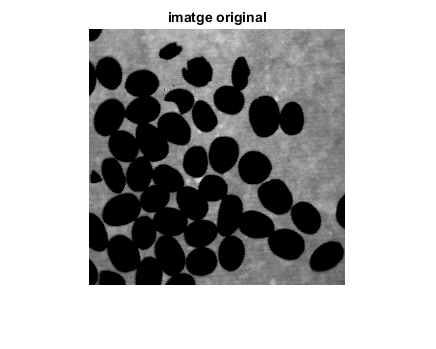

% Imatge original
im = imread("cafe.tif");
imshow(im),title('imatge original');

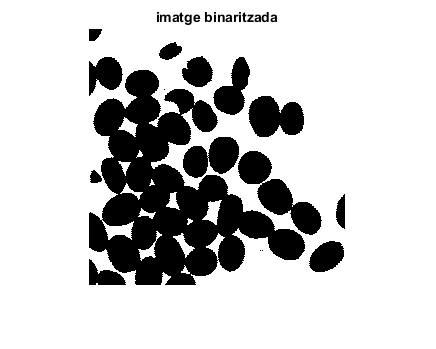


%Imatge binaritzada
b = imbinarize(im);
imshow(b),title('imatge binaritzada');

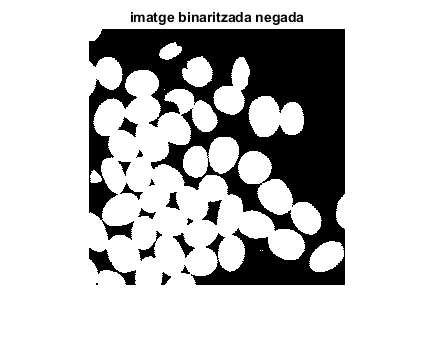


%Neguem la imatge per poder tractarla amb segmentació amb marques
bn = imcomplement(b);
imshow(bn),title('imatge binaritzada negada');

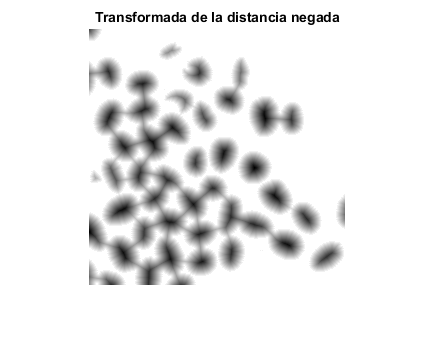


%Transformada de la distancia i negada
transNegada = -bwdist(~bn);
imshow(D,[]),title('Transformada de la distancia negada');

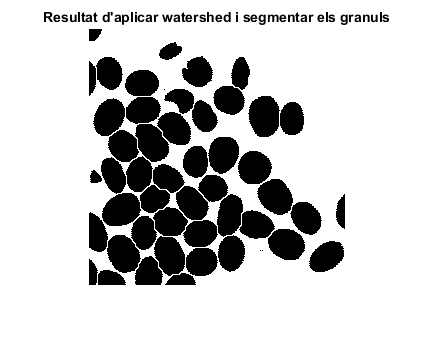


%Per suprimir la sobresegmentació i surtin granuls segmentats
transNegada2 = imhmin(transNegada,1);
L = watershed(D3);

%Aplicar transformació de watershed per segmentar
%%L = watershed(D);
bn2 = bn;
bn2(~L) = 0;
resultatInicial = imregionalmax(imcomplement(bn2));

%Resultat amb la imatge segmentada pero te una petita part de sobresegmentació
imshow(resultatInicial),title("Resultat d'aplicar watershed i segmentar els granuls");